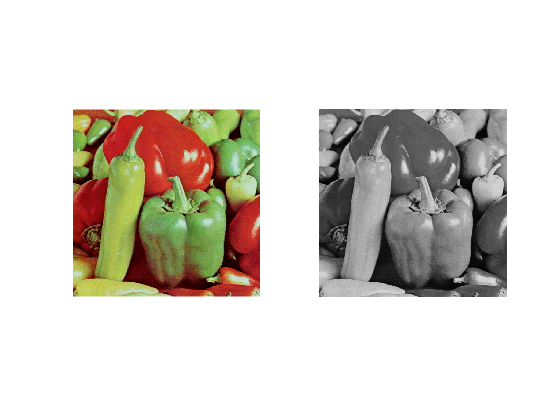

% Peppers Color is in a strange format. CData + Colormap
[peppers, map] = imread('peppers_color.tif');
if ~isempty(map)
    peppers = ind2rgb(peppers(:,:,1),map);
end

% Conversion to greyscale produces a double 0->1.
% Scale this to 0->255
% Convert to uint8 for display.
peppers_grey = uint8(rgb2gray(peppers)*255);
%peppers = uint8(peppers(:,:,1));
peppers = uint8(peppers * 255);
figure
subplot(1,2,1);
imshow(peppers);
subplot(1,2,2);
imshow(peppers_grey);

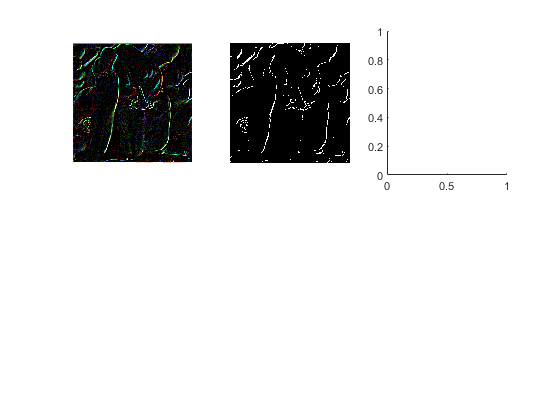


% Empty 3x3 Kernel
% [a b c;
%  d e f;
%  g h i ];
my_empty_kernel = [ 0 0 0; 0 0 0; 0 0 0 ];
output = derive(peppers);
figure
subplot(2,3,1);
imshow(output);
subplot(2,3,2);
imshow(imbinarize(greyderive(peppers_grey)))
subplot(2,3,3);

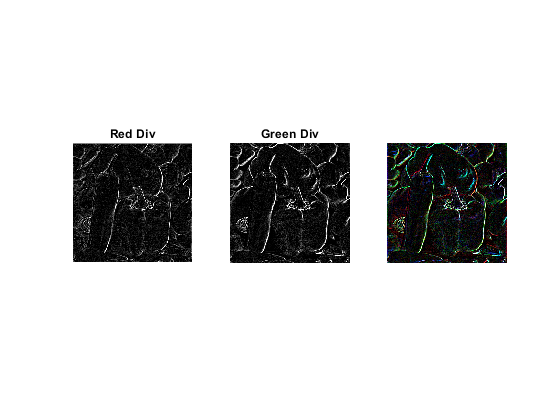

imshow(combineDiv(peppers));

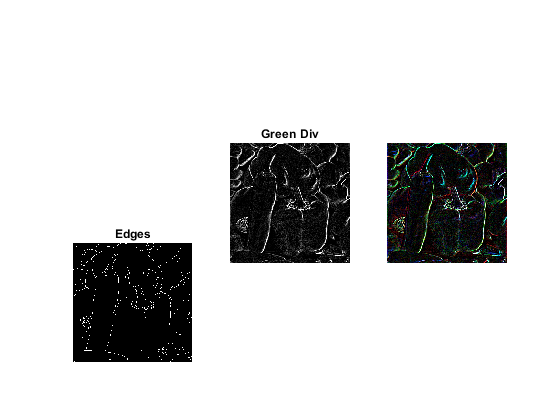

subplot(2,3,4);
imshow(edge(peppers_grey, 'Prewitt'));
title('Edges');

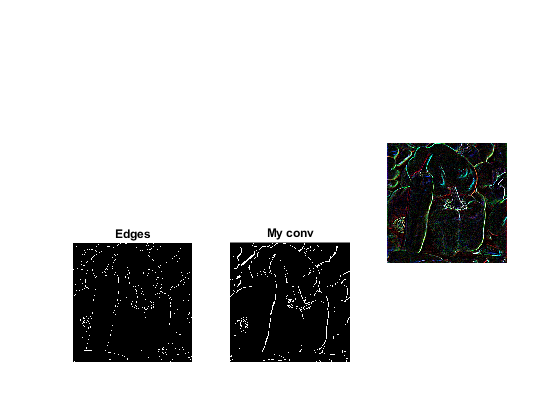

subplot(2,3,5);
imshow(imbinarize(combGreyDeriv(peppers_grey)));
title('My conv');

HSV test

hsvPeppers = uint8(rgb2hsv(peppers));

outputHSVDiv = (combineDiv(hsvPeppers));
figure
subplot(1,1,1);
imshow(outputHSVDiv);
title("HSV First Div");

function firstDerivative = derive(image)
    [r, g, b] = imsplit(image);
    firstDiv = [ -2 -1 0; -1 0 1; 0 1 2 ];
    rd = uint8(conv2(r,firstDiv));
    gd = uint8(conv2(g,firstDiv));
    bd = uint8(conv2(b, firstDiv));
    firstDerivative = cat(3,rd,gd,bd);
end

function firstDivCombine = combineDiv(image)
    [r, g, b] = imsplit(image);
    xfirstDiv = [ -1 0 1; -1 0 1; -1 0 1 ];
    yfirstDiv = [-1 -1 -1; 0 0 0; 1 1 1 ];
    rdx = conv2(r, xfirstDiv);
    gdx = conv2(g, xfirstDiv);
    bdx = conv2(b, xfirstDiv);
    rdy = conv2(r, yfirstDiv);
    gdy = conv2(g, yfirstDiv);
    bdy = conv2(b, yfirstDiv);
    
    figure
    subplot(1,3,1);
    imshow(uint8(rdx) + uint8(rdy));
    title("Red Div");
    subplot(1,3,2);
    imshow(uint8(gdx) + uint8(gdy));
    title("Green Div");
    subplot(1,3,3);
    imshow(uint8(bdx) + uint8(bdy));
    title("Blue Div");

    r = uint8(rdx) + uint8(rdy);
    g = uint8(gdx) + uint8(gdy);
    b = uint8(bdx) + uint8(bdy);
    firstDivCombine = cat(3,r,g,b);
 end

function firstDerivative = combGreyDeriv(image)
    xfirstDiv = [ -1 0 1;
                  -1 0 1;
                  -1 0 1 ];
    yfirstDiv = [-1 -1 -1;
                  0  0  0;
                  1  1  1];
%xfirstDiv = [ -2 -1 0; -1 0 1; 0 1 2 ];
x = conv2(image, xfirstDiv);
y = conv2(image, yfirstDiv);
firstDerivative = uint8(x) + uint8(y);
end

function firstDerivative = greyderive(image)
 firstDiv = [ -2 -1 0; -1 0 1; 0 1 2 ];
 rd = uint8(conv2(image,firstDiv));
 
 firstDerivative = rd;
end